clc;
clear;

gnss_origin = [42.29322828071904, -71.26433857013662, 50];

tag_gnss_maps = [
    42.29330440324687, -71.26442138250495
    42.2934381493404, -71.26438618506542
    42.29353413949006, -71.26432834773381
    42.29358012016498, -71.26418765493307
    42.29364617294784, -71.26421425112251
    42.29362480297451, -71.2641274533543
    42.29373369699089, -71.26406691508114
    42.293800629254704, -71.26384894996616
    42.29378541164158, -71.2636193059333
    42.29365661112291, -71.26348053982403
    42.29355540678682, -71.26347651168008
    42.29332491558013, -71.26372656047833
    42.29324649784491, -71.26385982422015
    42.29319488913584, -71.2640152976136
    42.29317839266936, -71.26416410076888
    ];

posxy_meas = [
    -6.860 8.502
    -4.188 23.775
    0.847 34.282
    12.418 39.531
    10.230 46.645
    17.400 44.631
    22.329 56.340
    40.329 63.738
    59.013 62.425
    70.776 48.080
    71.186 36.752
    50.138 10.889
    39.286 2.134
    26.494 -3.701
    14.098 -5.531
    ];

tag_gnss_map_append = [tag_gnss_maps 50*ones(size(tag_gnss_maps,1),1)];
[posxy_gnss_x, posxy_gnss_y, posxy_gnss_alt] = latlon2local(tag_gnss_map_append(:,1),tag_gnss_map_append(:,2),tag_gnss_map_append(:,3), gnss_origin);
posxy_gnss = [posxy_gnss_x posxy_gnss_y];

posxy_meas_append = [posxy_meas 0*ones(size(posxy_meas,1),1)];
[lat_meas, lon_meas, alt_meas] = local2latlon(posxy_meas_append(:,1),posxy_meas_append(:,2),posxy_meas_append(:,3),gnss_origin);
latlon_meas = [lat_meas lon_meas];

norm_diff = vecnorm((posxy_gnss - posxy_meas)');

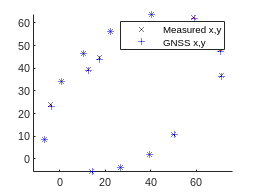

scatter(posxy_meas(:,1), posxy_meas(:,2), 'kx');
hold on;
scatter(posxy_gnss(:,1), posxy_gnss(:,2), 'b+');

for idx=1:size(posxy_gnss,1)
    xy_gnss = posxy_gnss(idx,:);
    xy_meas = posxy_meas(idx,:);
    plot([xy_gnss(1),xy_meas(1)], [xy_gnss(2) xy_meas(2)], '--r');
end

axis equal;
legend(["Measured x,y", "GNSS x,y"])
hold off;

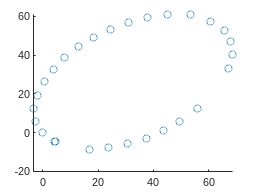

gmaps_waypoints = [
    42.293187847876155, -71.26428780494085;
    42.29322802507352, -71.2643380963595;
    42.29328060260171, -71.26437162397193;
    42.293341116306244, -71.2643796705989;
    42.293401133942396, -71.26436156568788;
    42.293464127595, -71.26433139083669;
    42.29352265707402, -71.26429115770176;
    42.293577714418575, -71.26424086628205;
    42.29362681957457, -71.26418118713191;
    42.293671460592236, -71.26411547301156;
    42.29370766939691, -71.26404104171058;
    42.29373891807249, -71.2639625870975;
    42.29376223056638, -71.26387809751415;
    42.29377711087715, -71.26379226682633;
    42.293775622846226, -71.26369168398904;
    42.29374338216772, -71.26360250053996;
    42.293701717266444, -71.26354215083757;
    42.293652116156096, -71.26351734040314;
    42.29358912268985, -71.26350661156663;
    42.29352662517454, -71.26352337537286;
    42.29333814022718, -71.2636594974793;
    42.29327911455959, -71.26373862264556;
    42.29323893739365, -71.26380903063226;
    42.29320322433679, -71.26388480303636;
    42.293178423590945, -71.26396661041069;
    42.293159575016844, -71.26405177054752;
    42.29315015072802, -71.2641342484741;
    42.29318635982993, -71.26428378162555;
    42.29322852108677, -71.2643394374622;
];

gmaps_waypoints_append = [gmaps_waypoints 50*ones(size(gmaps_waypoints,1),1)];
[gmaps_waypoints_x, gmaps_waypoints_y, gmaps_waypoints_alt] = latlon2local(gmaps_waypoints_append(:,1),gmaps_waypoints_append(:,2),gmaps_waypoints_append(:,3), gnss_origin);
gmaps_waypoints_xy = [gmaps_waypoints_x gmaps_waypoints_y];

scatter(gmaps_waypoints_xy(:,1),gmaps_waypoints_xy(:,2));


gmaps_waypoints_xy

gmaps_waypoints_xy =     4.1866   -4.4913
    0.0391   -0.0284
   -2.7259    5.8119
   -3.3895   12.5338
   -1.8964   19.2005
    0.5921   26.1978
    3.9101   32.6993
    8.0576   38.8150
   12.9793   44.2697
   18.3987   49.2284
